% Load profile
load("..\Final Models and Data\NewBuildingVariables.mat")
HourlyElectricalLoad(:,"29-Feb-2024: Thursday") = [];
HourlyHeatingLoad(:,"29-Feb-2024: Thursday") = [];
HourlyCoolingLoad(:,"29-Feb-2024: Thursday") = [];

Hourly_electrical_load_array=table2array(HourlyElectricalLoad);
Hourly_heating_load_array=table2array(HourlyHeatingLoad);
Hourly_cooling_load_array=table2array(HourlyCoolingLoad);
Hourly_total_load_array=Hourly_electrical_load_array + ...
    (Hourly_heating_load_array./4) + ...
    (Hourly_cooling_load_array./4);

% Solar energy profile
load("..\Final Models and Data\SolarVariables.mat")
Hourly_solar_roof_array=table2array(RoofHourlySolarEnergy);
Hourly_solar_quad_array=table2array(QuadHourlySolarEnergy);
Hourly_solar_wall_array=table2array(WallHourlySolarEnergy);
Hourly_solar_array = Hourly_solar_roof_array + Hourly_solar_wall_array + Hourly_solar_quad_array

Hourly_solar_array =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        


%Wind energy profile (x9 turbines)
load("..\Final Models and Data\WindVariables.mat")
HourlySavoniusWind_array=table2array(HourlySavoniusWind);
Hourly_wind_x9=HourlySavoniusWind_array.*4.5;%DONT FORGET THIS
%Total energy
Hourly_total_array=Hourly_wind_x9+Hourly_solar_array;

%BESS characteristics

Optimise=zeros(100,1);
Total_battery_energy=4800

Total_battery_energy = 4800

Grid_power=zeros(24,365);
Load_power=zeros(24,365);
Battery_power=zeros(24,365);
Battery_soc=zeros(24,365);
Grid_energy_total=0;
Returned_grid_energy=zeros(24,365);
Wind_energy_total=0;
Battery_supplied_total=0;
Load_energy_total=0;
System_self_sufficiency=0;
Produced_energy_total=0;

%Everything in Kwh
Battery_max_power=1200; %Units?
%Battery_v_nom=51.2;
% Q_nom=1
% Q_current=0.2
%Battery_max_current=280;
Max_charge_rate=Battery_max_power;
Max_discharge_rate=Battery_max_power;
Min_soc=0.2;
Batttery_energy_minimum=Min_soc*Total_battery_energy;

Battery_energy_current=Total_battery_energy*1

Battery_energy_current = 4800

Battery_soc_current=Battery_energy_current/Total_battery_energy

Battery_soc_current = 1



%Conversion losses
system_efficiency=0.95;
rate_of_discharge=0.05;


%Control logic
for m=1:365
    for n=1:24
        % n=1
        % m=1
        Current_power_demand=Hourly_total_load_array(n,m);
        % Current_power_demand=500
        % Current_produced_power=2000
        Current_produced_power=Hourly_total_array(n,m);
        Produced_energy_total=Produced_energy_total+Current_produced_power;
        Load_energy_total=Load_energy_total+Current_power_demand;
        Power_flow=Current_power_demand-Current_produced_power;
        %Power demand exeeds power supplied by source -> try to discharge
        %battery
        if Power_flow > 0
            %Check enough energy is in the battery to supply for the hour
            Battery_available_energy=(Battery_energy_current-Batttery_energy_minimum)*system_efficiency;

            %There is enough to supply for the whole hour
            if Battery_available_energy>Power_flow
                if abs(Power_flow)>Battery_max_power*system_efficiency
                    %Supply energy from battery, adjust battery to new SOC,
                    %check if grid connection necessary
                    Battery_power(n,m)=(Battery_max_power*system_efficiency);
                    Battery_energy_current=Battery_energy_current-Battery_max_power;
                    Battery_soc_current=Battery_energy_current/Total_battery_energy;
                    Battery_soc(n,m)=Battery_soc_current;
                    %Only battery max power can be subtracted as a max, power
                    %flow is negative when the demand exceeds the supply from
                    %the renewable
                    Grid_requirement=Power_flow-Battery_max_power*system_efficiency;
                    Grid_power(n,m)=Grid_requirement;
                else
                    Battery_energy_current=Battery_energy_current-(Power_flow/system_efficiency);
                    Battery_soc_current=Battery_energy_current/Total_battery_energy;
                    Battery_soc(n,m)=Battery_soc_current;
                    Battery_power(n,m)=(Power_flow/system_efficiency);
                end
                %There is not enough energy to supply for the whole hour
            else
                %Discharge as much as possible, down to min of battery
                Battery_power(n,m)=(Battery_energy_current-Batttery_energy_minimum)*system_efficiency;
                Battery_energy_current=Batttery_energy_minimum;
                Grid_requirement=Power_flow-(Battery_available_energy);
                Grid_power(n,m)=Grid_requirement;
                Battery_soc_current=Battery_energy_current/Total_battery_energy;
                Battery_soc(n,m)=Battery_soc_current;
            end
            %Power demand lower than energy production
        else
            %Charge battery with whole overcharge if possible
            if Battery_energy_current-Power_flow<Total_battery_energy
                if abs(Power_flow)<Battery_max_power*system_efficiency
                    Battery_energy_current=Battery_energy_current-Power_flow*system_efficiency;
                    Battery_soc_current=Battery_energy_current/Total_battery_energy;
                    Battery_soc(n,m)=Battery_soc_current;
                else
                    Battery_energy_current=Battery_energy_current+Battery_max_power*system_efficiency;
                    Battery_soc_current=Battery_energy_current/Total_battery_energy;
                    Battery_soc(n,m)=Battery_soc_current;
                    Returned_grid_energy(n,m)=-(Power_flow+Battery_max_power);
                    Battery_soc_current=Battery_energy_current/Total_battery_energy;
                    Battery_soc(n,m)=Battery_soc_current;
                    %If energy too much, return to grid
                end
            else
                if Battery_soc_current==1
                    Returned_grid_energy(n,m)=-Power_flow;
          
                    Battery_soc(n,m)=Battery_soc_current;
                else
                    Can_be_charged_by=(Total_battery_energy-Battery_energy_current);
                    if abs(Power_flow)<Battery_max_power*system_efficiency;
                        Returned_grid_energy(n,m)=-(Power_flow+Can_be_charged_by);
                        
                        Battery_energy_current=Total_battery_energy;
                        Battery_soc_current=Battery_energy_current/Total_battery_energy;
                        Battery_soc(n,m)=Battery_soc_current;
                    else
                        Battery_energy_current=Battery_energy_current+Battery_max_power*system_efficiency;
                        Battery_soc_current=Battery_energy_current/Total_battery_energy;
                        Battery_soc(n,m)=Battery_soc_current;
                        Returned_grid_energy(n,m)=-Power_flow+(Battery_max_power*system_efficiency);
                
                    end
                end
            end
        end
     end
 end

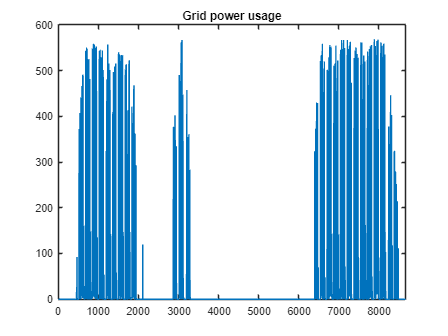


yearhours=linspace(1,(24*365),(24*365));
%Graphs and metrics
% Grid_power
figure;
Grid_power_1D = reshape(Grid_power,[length(yearhours) 1]);
plot(yearhours,Grid_power_1D)
title('Grid power usage')
xlim([0 8670])

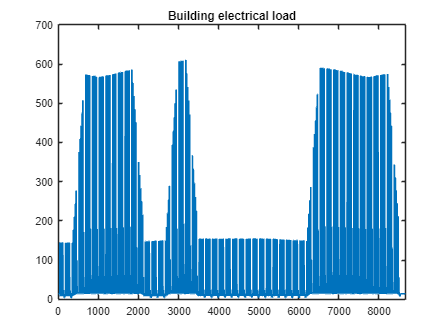

% Load_power
figure;
Load_power_1D = reshape(Hourly_total_load_array,[length(yearhours) 1]);
plot(yearhours,Load_power_1D)
xlim([0 8670])
title('Building electrical load')

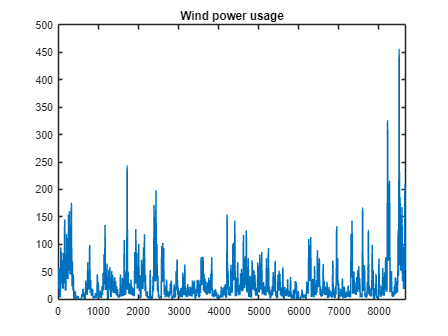

%Wind power
Wind_power_1D= reshape(Hourly_wind_x9,[length(yearhours) 1]);
plot(yearhours,Wind_power_1D)
xlim([0 8670])
title('Wind power usage')

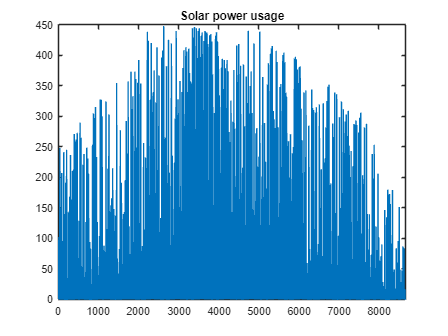

%Solar
Solar_power_1D= reshape(Hourly_solar_array,[length(yearhours) 1]);
plot(yearhours,Solar_power_1D)
xlim([0 8670])
title('Solar power usage')

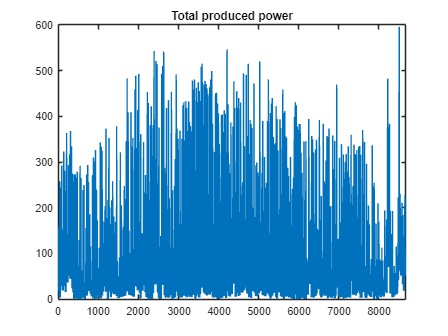

%Total produced power
total_power_1D= reshape(Hourly_total_array,[length(yearhours) 1]);
plot(yearhours,total_power_1D)
xlim([0 8670])
title('Total produced power')

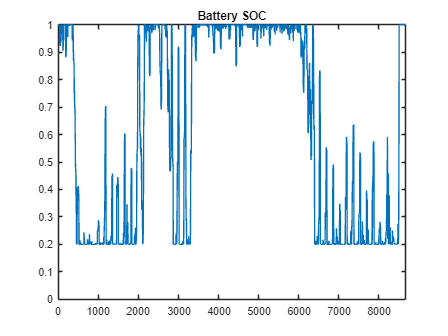

% % Battery_power
% figure(3)
Battery_power_1D = reshape(Battery_power,[length(yearhours) 1]);
% plot(hours,Battery_power_1D)
% xlim([0 8670])
% title('Battery power usage')
%Battery SOC
figure;
Battery_soc_1D = reshape(Battery_soc,[length(yearhours) 1]);
plot(yearhours,Battery_soc_1D)
ylim([0,1])
xlim([0 8670])
title('Battery SOC')

Returned_energy_1D = reshape(Returned_grid_energy,[length(yearhours) 1]);
%Energy deficit
Energy_defecit=Hourly_total_load_array-Hourly_total_array

Energy_defecit =    -5.4696   10.9135  -17.5305  -14.4819   -5.2626  -14.2150  -34.5217   -1.9637  -25.5843  -22.6578  -37.6424  -39.6592  -30.8009  -44.7124   -9.2202   -1.2466   13.3757    9.1298   12.6249   11.8835   12.3618   13.5617   13.3331   13.8845   10.7275    7.5892   10.0536   13.2886    2.7544    5.8702   -8.5262   -3.4647  -18.9853    2.1681    7.3891    7.7853   12.1545   12.5892   10.2646   11.7385   -1.2466    3.8683   10.6639    8.7925   11.7385    5.7536   -2.1465  -13.4241  -31.1641   -2.7030
   -6.1914   10.7993  -18.6995  -15.5379   -5.9767  -15.2611  -36.3208   -2.5555  -27.0519  -24.0169  -39.5572  -41.6488  -32.4620  -46.8894  -10.0811   -1.8118   13.3528    8.9494   12.5741   11.8052   12.3012   13.5456   13.3086   13.8804   10.6064    7.3517    9.9075   13.2624    2.3376    5.5690   -9.3613   -4.1121  -20.2082    1.7296    7.1442    7.5551   12.0863   12.5371   10.1263   11.6549   -1.8118    3.4928   10.5404    8.5996   11.6549    5.4480   -2.7450  -14.4409  

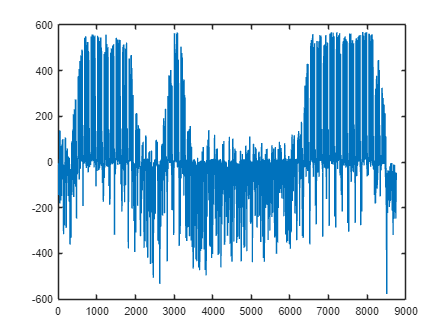

Energy_defecit_1D=reshape(Energy_defecit,[length(yearhours) 1]);
plot(yearhours,Energy_defecit_1D)

%Sense check - Battery supplied total value isnt currently correctly
%updated
Returned_grid_energy_total=sum(sum(Returned_grid_energy))

Returned_grid_energy_total = 2.5379e+05

Used_grid_energy_total=sum(sum(Grid_power))

Used_grid_energy_total = 4.2657e+05


% System_self_sufficiency - unsure about current accuracy on this
Self_sufficiency_NETINGORINGRETURNED=(Produced_energy_total)/Load_energy_total

Self_sufficiency_NETINGORINGRETURNED = 0.8284


% Optimise(1,1)=Self_sufficiency;

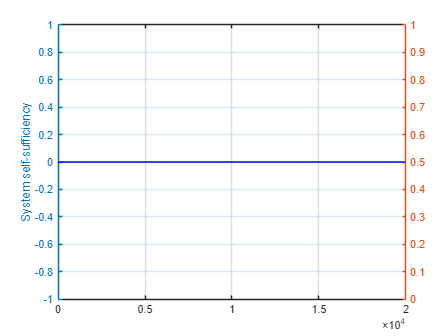

% (Section probably unnecessary here)
xnew = linspace(0, 20000, 100);     % x-axis data (100 to 100,000)
costy = (800000/2400) .* xnew;
% Plot
figure;
% Plot Optimise on the left y-axis
yyaxis left
plot(xnew, Optimise, 'b');  % 'b' for blue line, you can change the color/style
ylabel('System self-sufficiency')
xlim([0 20000])% Label for left y-axis              % Set y-axis limits for Optimise
% Plot costy on the right y-axis
% yyaxis right
% plot(xnew, costy, 'r');     % 'r' for red line, you can change the color/style
% ylabel('Cost (GBP)')       % Label for right y-axis
% ylim([0 2000000])  % Adjust the y-axis limits for costy
% % Set x-axis label
% xlabel('System Size (kWh)')
% % Title
% %title('System self sufficiency vs Cost')
% % Optional: grid
grid on

% Variation of wind over a day
% Occupancy Calcs

startDate = datetime('2023-01-01');
endDate = datetime('2023-12-31');
dates = startDate:endDate;

% Get full day names
dayNames = string(day(dates, 'name')); % 'dddd' gives full day names

% Create time strings (optional, if needed for another purpose)
times = hours(0:23);
timeStrings = string(datetime(2023,1,1) + times, 'HH:mm');  % Create datetime starting from a base date

% Preallocate the VarNames cell array
VarNames = cell(1, length(dates));

% Loop through each date and create formatted strings
for i = 1:length(dates)
    VarNames{i} = sprintf('%s: %s', datestr(dates(i), 'dd-mmm-yyyy'), dayNames(i));
end

HourlyUsedGridPower = array2table(Grid_power,'RowNames',string(timeStrings),'VariableNames',string(VarNames));
HourlyReturnedGridPower = array2table(Returned_grid_energy,'RowNames',string(timeStrings),'VariableNames',string(VarNames));
HourlyBatteryPower = array2table(Battery_power,'RowNames',string(timeStrings),'VariableNames',string(VarNames));

save("GridValues.mat", "HourlyUsedGridPower","HourlyReturnedGridPower","HourlyBatteryPower");

%Monthly

timestamps = datetime(2023,1,1,0,0,0):hours(1):datetime(2023,12,31,23,0,0); % Hourly timestamps for 2023

% Create timetables for each energy source
tt_grid = timetable(timestamps', Grid_power_1D);
tt_wind = timetable(timestamps', Wind_power_1D);
tt_solar = timetable(timestamps', Solar_power_1D);
tt_battery = timetable(timestamps', Battery_power_1D); % Optional: If battery data is available
tt_load = timetable(timestamps', Load_power_1D)

tt_load = 8760×1 timetable
            Time            Load_power_1D
    ____________________    _____________

    01-Jan-2023 00:00:00       13.994    
    01-Jan-2023 01:00:00       13.994    
    01-Jan-2023 02:00:00       13.994    
    01-Jan-2023 03:00:00       13.994    
    01-Jan-2023 04:00:00       13.994    
    01-Jan-2023 05:00:00       13.994    
    01-Jan-2023 06:00:00       13.994    
    01-Jan-2023 07:00:00       13.994    
    01-Jan-2023 08:00:00       13.994    
    01-Jan-2023 09:00:00       13.994    
    01-Jan-2023 10:00:00       13.994    
    01-Jan-2023 11:00:00       13.994    
    01-Jan-2023 12:00:00       13.994    
    01-Jan-2023 13:00:00       13.99

tt_returned = timetable(timestamps', Returned_energy_1D)

tt_returned = 8760×1 timetable
            Time            Returned_energy_1D
    ____________________    __________________

    01-Jan-2023 00:00:00          5.4696      
    01-Jan-2023 01:00:00          6.1914      
    01-Jan-2023 02:00:00          8.3032      
    01-Jan-2023 03:00:00          11.648      
    01-Jan-2023 04:00:00          15.979      
    01-Jan-2023 05:00:00          20.973      
    01-Jan-2023 06:00:00          26.262      
    01-Jan-2023 07:00:00          31.451      
    01-Jan-2023 08:00:00          36.158      
    01-Jan-2023 09:00:00          135.66      
    01-Jan-2023 10:00:00          144.62      
    01-Jan-2023 11:00:00          122.56      
    01-Jan-2023 12:00:00

% Group the data by month and calculate the sum for each month
monthly_sum_grid = retime(tt_grid, 'monthly', 'sum');   
monthly_sum_wind = retime(tt_wind, 'monthly', 'sum');   
monthly_sum_solar = retime(tt_solar, 'monthly', 'sum');   
monthly_sum_battery = retime(tt_battery, 'monthly', 'sum');
monthly_sum_load = retime(tt_load, 'monthly', 'sum');  
monthly_sum_returned = retime(tt_returned, 'monthly', 'sum');  
% Optional: Battery power + returned to grid

% Combine monthly sums into a matrix for stacked bar plot
monthly_data = [monthly_sum_grid.Grid_power_1D, ...
                monthly_sum_wind.Wind_power_1D, ...
                monthly_sum_solar.Solar_power_1D, ...
                monthly_sum_battery.Battery_power_1D];  % Optional: Include battery data if available
monthly_load_data=[monthly_sum_load.Load_power_1D,monthly_sum_returned.Returned_energy_1D]

monthly_load_data = 1.0e+05 *

    0.6700    0.1544
    1.1955         0
    1.1034    0.0116
    0.4475    0.3308
    1.0004    0.2122
    0.3424    0.5730
    0.3844    0.4888
    0.3690    0.3502
    0.5890    0.1631
    1.3969         0


yearly_sum_load=sum(Load_power_1D)

yearly_sum_load = 9.5108e+05

yearly_sum_wind=sum(Wind_power_1D)

yearly_sum_wind = 2.6805e+05

yearly_sum_solar=sum(Solar_power_1D)

yearly_sum_solar = 5.1984e+05

yearly_sum_battery=sum(Battery_power_1D)

yearly_sum_battery = 9.5755e+04

yearly_sum_grid=sum(Grid_power_1D)

yearly_sum_grid = 4.2657e+05

yearly_sum_returned=sum(Returned_energy_1D)

yearly_sum_returned = 2.5379e+05

System_self_sufficiency=(yearly_sum_solar+yearly_sum_wind-yearly_sum_returned)/yearly_sum_load

System_self_sufficiency = 0.5616

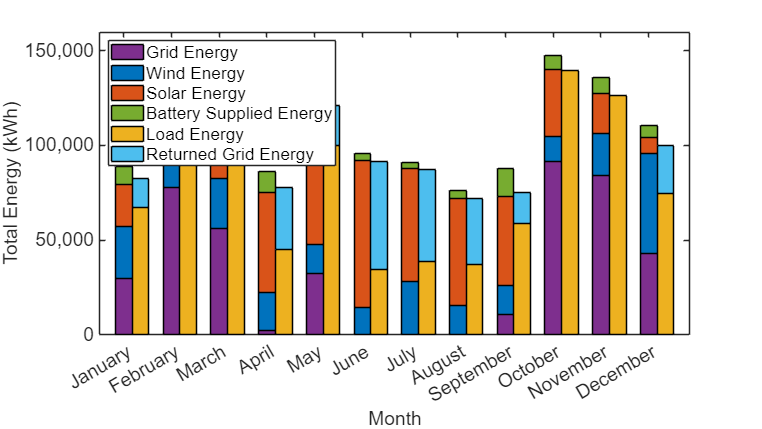

% Create stacked bar plot
figure;
hold on;
colors = [[0 0.4470 0.7410],
    [0.8500 0.3250 0.0980],
    [0.9290 0.6940 0.1250],
    [0.4940 0.1840 0.5560],
    [0.4660 0.6740 0.1880],
    [0.3010 0.7450 0.9330],
    [0.6350 0.0780 0.1840]];
% Adjust the BarWidth so the bars don't overlap and fit nicely
bar_width = 0.35; % Decrease the bar width for both sets of bars

% Plot stacked bar for energy sources (Grid, Wind, Solar, Battery)
h1 = bar(monthly_data, 'stacked');
set(h1, 'BarWidth', bar_width);  % Adjust the width of the bars for the energy breakdown

% Plot the load bar next to the stacked bar (slightly offset)
h2 = bar(monthly_load_data, 'stacked'); % Light grey for Load bar
set(h2, 'BarWidth', bar_width);  % Adjust the width of the bars for the load breakdown

% Adjust the X positions of the load bars to shift them to the right
for k = 1:length(h2)
    h2(k).XData = h2(k).XData + bar_width;  % Offset the Load bar by bar_width to the right of the energy breakdown bars
end
%Assign colours
h1(1).FaceColor = colors(4, :);  % Grid Power (Purple)
h1(2).FaceColor = colors(1, :);  % Wind Power (Blue)
h1(3).FaceColor = colors(2, :);  % Solar Power (Orange)
h1(4).FaceColor = colors(5, :);  % Battery Power (Green)

% Assign colors to each component in the load bars (h2)
h2(1).FaceColor = colors(3, :);  % Electrical Load (Yellow)
h2(2).FaceColor = colors(6, :);  % Returned Energy (Light Blue)
xlabel('Month',FontSize=28);
ylabel('Total Energy (kWh)', FontSize=28);
xticks(1:12); % Monthly ticks
xticklabels({'January', 'February', 'March', 'April', 'May', 'June', 'July', 'August', 'September', 'October', 'November', 'December'});
fontsize(gca,24,"pixels");
ax = gca;
ax.YAxis.Exponent = 0;
ax.YLim = [ax.YLim(1),ax.YLim(2)+10000];
ytickformat('%,.0f')
% Adjust the x-axis limits to reduce the space between the bars and axis
xlim([0.5, 12.85]);  % Set x-axis limits to reduce the gap between the bars and the axis

% Add legend for different energy sources and load
legend([h1, h2], {'Grid Energy', 'Wind Energy', 'Solar Energy', 'Battery Supplied Energy', 'Load Energy', 'Returned Grid Energy'}, 'Location', 'northwest');

grid off; % Optional: Add gridlines for better readability
box on
hold off;

set(gcf, 'Units', 'pixels', 'Position', get(0, 'ScreenSize'));
ax = gca;
exportgraphics(ax,'EnergyBreakdown.eps','Resolution',300) 